# TAP 2

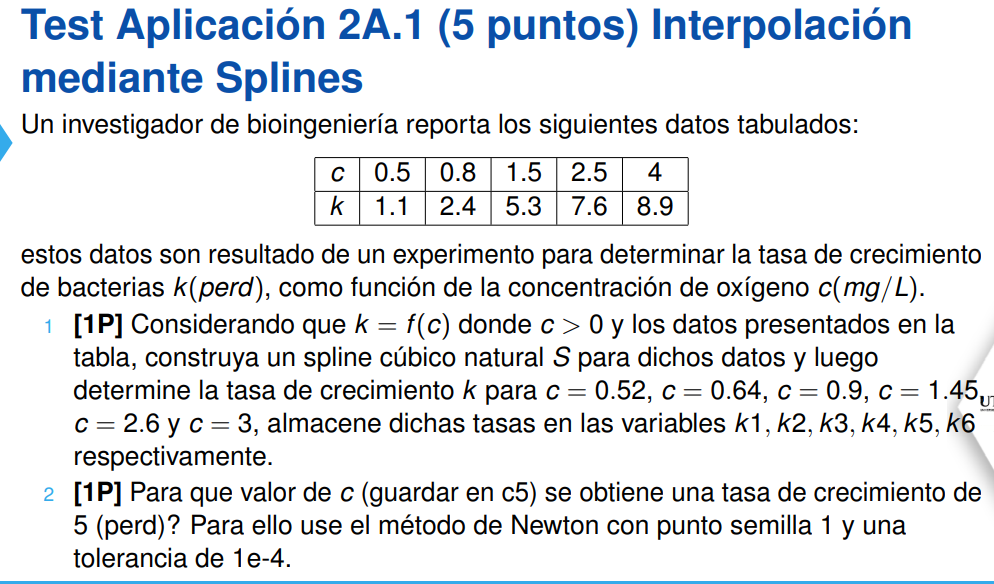

c = [0.5 0.8 1.5 2.5 4];
k = [1.1 2.4 5.3 7.6 8.9];

% item 1)
k_c = splinenatural(c,k)

k_c =    0.270620148792741                   0   4.308977519941985   1.100000000000000
  -0.836078593874100   0.243558133913467   4.382044960116025   2.400000000000000
   0.318216098622191  -1.512206913222143   3.493990814599952   5.300000000000000
   0.123901914967905  -0.557558617355571   1.424225284022238   7.600000000000000



% c = 0.52 -> [0.5 - 0.8] (1)
cc = 0.52;
x = c(1);
k1 = k_c(1,1)*((cc - x)^3) + k_c(1,2)*((cc - x)^2) + k_c(1,3)*(cc - x) + k_c(1,4)

k1 =    1.186181715360030



% c = 0.64 -> [0.5 - 0.8] (1)
cc = 0.64;
x = c(1);
k2 = k_c(1,1)*((cc - x)^3) + k_c(1,2)*((cc - x)^2) + k_c(1,3)*(cc - x) + k_c(1,4)

k2 =    1.703999434480165



% c = 0.9 -> [0.8 - 1.5] (2)
cc = 0.9;
x = c(2);
k3 = k_c(2,1)*((cc - x)^3) + k_c(2,2)*((cc - x)^2) + k_c(2,3)*(cc - x) + k_c(2,4)

k3 =    2.839803998756863



% c = 1.45 -> [0.8 - 1.5] (2)
cc = 1.45;
x = c(2);
k4 = k_c(2,1)*((cc - x)^3) + k_c(2,2)*((cc - x)^2) + k_c(2,3)*(cc - x) + k_c(2,4)

k4 =    5.121624451811181



% c = 2.6 -> [2.5 - 4] (4)
cc = 2.6;
x = c(4);
k5 = k_c(4,1)*((cc - x)^3) + k_c(4,2)*((cc - x)^2) + k_c(4,3)*(cc - x) + k_c(4,4)

k5 =    7.736970844143636



% c = 3 -> [2.5 - 4] (4)
cc = 3;
x = c(4);
k6 = k_c(4,1)*((cc - x)^3) + k_c(4,2)*((cc - x)^2) + k_c(4,3)*(cc - x) + k_c(4,4)

k6 =    8.188210727043215



a = [0.52 0.64 0.9 1.45 2.6 3];
b = [k1 k2 k3 k4 k5 k6];

plot(a, b, 'ob')
hold off

% item 2)
% k = 5 -> [0.8 - 1.5] (2)

syms c
f = k_c(2,1)*((c - 0.8)^3) + k_c(2,2)*((c - 0.8)^2) + k_c(2,3)*(c - 0.8) + k_c(2,4) - 5

$$f = \frac{4933744012374823\,c}{1125899906842624}+\frac{5038\,{\left(c-\frac{4}{5}\right)}^{2}}{20685}-\frac{24212\,{\left(c-\frac{4}{5}\right)}^{3}}{28959}-\frac{8592918709613351}{1407374883553280}$$

f = matlabFunction(f)

f = function_handle with value:
    @(c)c.*4.382044960116025+(c-4.0./5.0).^2.*2.435581339134639e-1-(c-4.0./5.0).^3.*8.360785938740979e-1-6.10563596809282



x0 = 1;
Tol = 1e-4;

z = newton(f, x0, Tol);

c5 = z(end)

c5 =    1.416984111676849


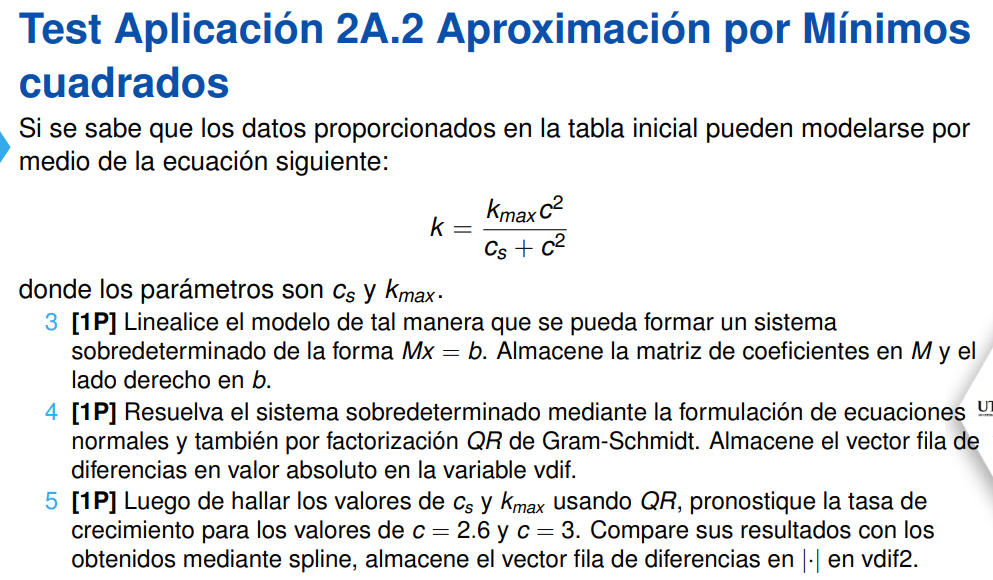

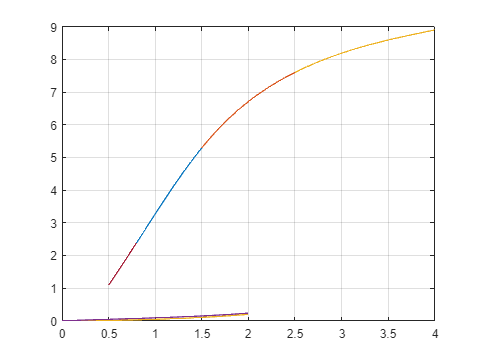

% item 3)
k = [1.1 2.4 5.3 7.6 8.9];
c = [0.5 0.8 1.5 2.5 4];
k_c = splinenatural(c,k);


k = [1.1 2.4 5.3 7.6 8.9]';
c = [0.5 0.8 1.5 2.5 4]';
M = [c.^2 -1*k]

M =    0.250000000000000  -1.100000000000000
   0.640000000000000  -2.400000000000000
   2.250000000000000  -5.300000000000000
   6.250000000000000  -7.600000000000000
  16.000000000000000  -8.900000000000000


b = (k).*(c.^2)

b = 1.0e+02 *

   0.002750000000000
   0.015360000000000
   0.119250000000000
   0.475000000000000
   1.424000000000000



% item 4)
% formulación de ecuaciones
sol_ec = inv(M'*M)*M'*b

sol_ec =   10.010248491812225
   1.993231191528652



% Factorización QR
[Q,R] = gs_c(M);
b = Q'*b;
sol_gs = sustireg(R,b)

sol_gs =   10.010248491812224
   1.993231191528651



vdif = [abs(sol_gs - sol_ec)]'

vdif = 1.0e-14 *

   0.177635683940025   0.155431223447522



% item 5)
k_max = sol_gs(1);
c_s = sol_gs(2);

k = @(c)((k_max * c * c)/(cs + c * c))

k = function_handle with value:
    @(c)((k_max*c*c)/(cs+c*c))



k5_gs = k(2.6);
k6_gs = k(3);

k5 = k_c(4,1)*((2.6 - 2.5)^3) + k_c(4,2)*((2.6 - 2.5)^2) + k_c(4,3)*(2.6 - 2.5) + k_c(4,4);
k6 = k_c(4,1)*((3 - 2.5)^3) + k_c(4,2)*((3 - 2.5)^2) + k_c(4,3)*(3 - 2.5) + k_c(4,4);

vdif2 = [abs(k5 - k5_gs) abs(k6 - k6_gs)]

vdif2 =    0.006193680375731   0.007035498264482


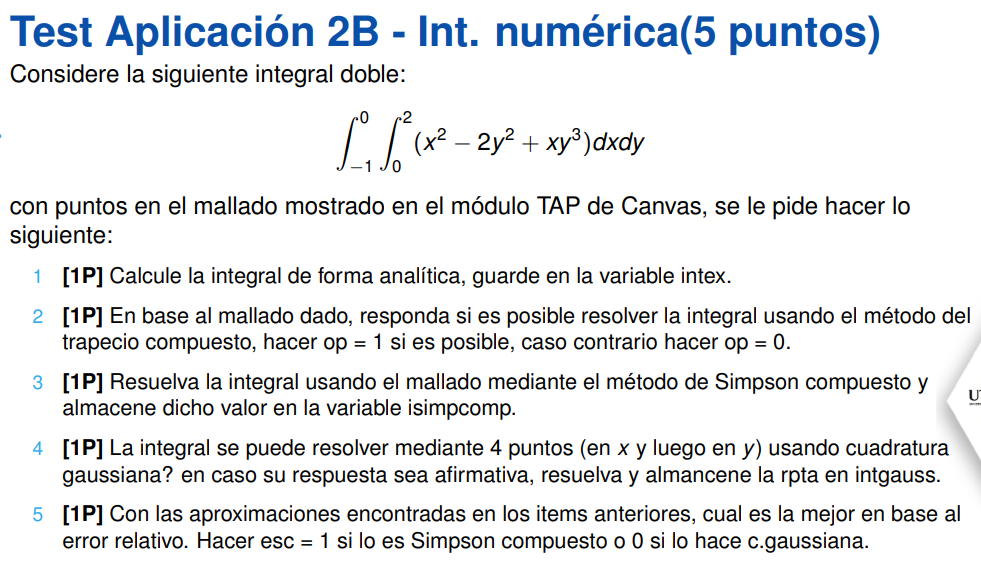

syms x y
f= @(x,y) (x^2-2*y^2+x*y^3 )

f = function_handle with value:
    @(x,y)(x^2-2*y^2+x*y^3)




% item 1)
I1 = int(f, x,0,2);
I2 = int(I1,y,-1,0) ;
intex = double(I2)

intex =    0.833333333333333



% itme 2)
op = 1

op =      1



% item 3)
f1 = @(x) (x.^2-2*y.^2+x*y^3)

f1 = function_handle with value:
    @(x)(x.^2-2*y.^2+x*y^3)



I1 = matlabFunction(int(f1,x,x1,x2))

I1 = function_handle with value:
    @(y)y.^2.*-4.0+y.^3.*2.0+8.0./3.0



a=-1;
b=-0.4;
c=0;

I2 = simp2(I1,a,b,h);

I3= simp(I1,b,c,h);

Itotal = I2+I3;

isimpcomp=Itotal

isimpcomp =    0.960542527103583



% item 4)
syms p q
fx = @(x,y) (x^2-2*y^2+x*y^3 )

fx = function_handle with value:
    @(x,y)(x^2-2*y^2+x*y^3)



x1=0;
x2=2;
y1=-1;
y2=0;

intgauss= gaussnp(fx,x1,x2,y1,y2,4)

intgauss =    0.833333333333333




% item 5)
err_simpson = abs(isimpcomp-intex)/abs(intex)

err_simpson =    0.152651032524300


err_gauss = abs(intex-intgauss)/abs(intex)

err_gauss =      0



if (err_simpson < err_gauss)
    esc = 1
else
    esc = 0
end

esc =      0


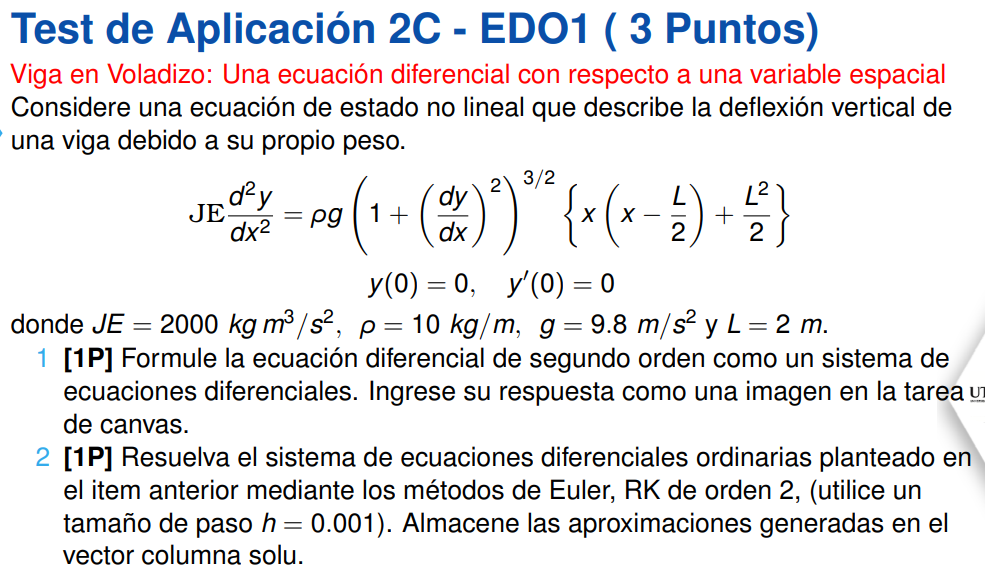

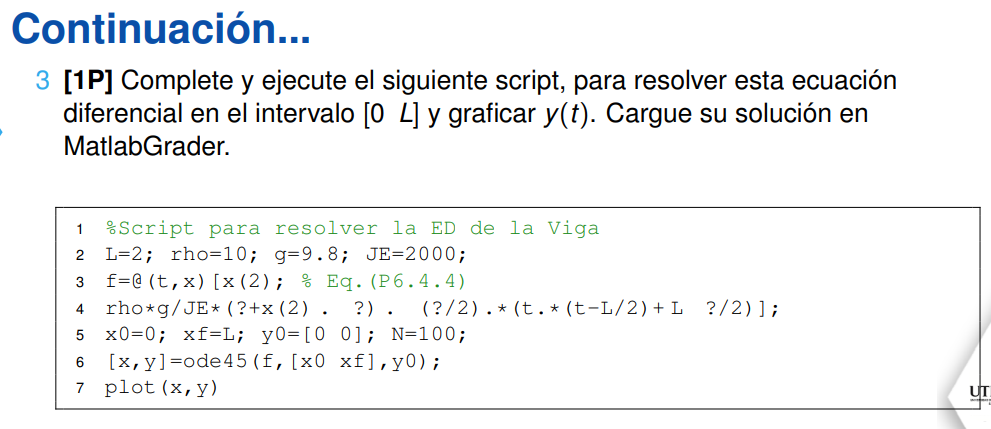

item 1)

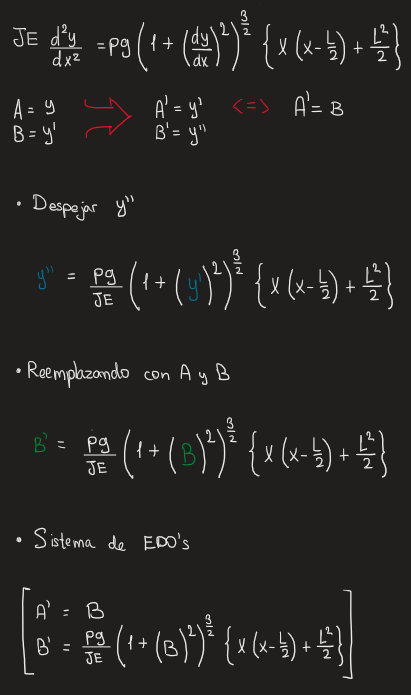

%item 2)
format long
JE = 2000;
p = 10;      
g = 9.8;   
L = 2;

f = @(x, y) [y(2); (p*g/JE) * (1 + y(2).^2).^(3/2) .* (x .* (x - L/2) + (L^2)/2)]

f = function_handle with value:
    @(x,y)[y(2);(p*g/JE)*(1+y(2).^2).^(3/2).*(x.*(x-L/2)+(L^2)/2)]



x0 = 0; xf = L;
y0 = [0; 0];
h = 0.001;

euler_sol = euler_sistema(f, x0, xf, y0, h);
rk2_sol = rk2_sistema(f, x0, xf, y0, h);

solu = [euler_sol(:, 2) rk2_sol(:, 2)]

solu =                    0                   0
                   0   0.000000049000000
   0.000000098000000   0.000000195951050
   0.000000293951050   0.000000440804302
   0.000000587804302   0.000000783511008
   0.000000979511008   0.000001224022520
   0.000001469022520   0.000001762290293
   0.000002056290293   0.000002398265880
   0.000002741265880   0.000003131900936
   0.000003523900936   0.000003963147218




% item 3
L=2; rho=10; g=9.8; JE=2000;
f=@(t,x)[x(2); rho*g/JE*(1 + x(2).^(2)).^(3/2).*(t.*(t-L/2)+ L^2/2)];
x0=0; xf=L; y0=[0 0]; N=100;
[x,y]=ode45(f,[x0 xf], y0)

x =                    0
   0.000512629883982
   0.001025259767963
   0.001537889651945
   0.002050519535926
   0.004613668955834
   0.007176818375742
   0.009739967795649
   0.012303117215557
   0.025118864315096


y =                    0                   0
   0.000000012875581   0.000050231292554
   0.000000051497925   0.000100449722009
   0.000000115860444   0.000150655301947
   0.000000205956552   0.000200848045949
   0.000001042211006   0.000451619702204
   0.000002520821677   0.000702072496850
   0.000004640973452   0.000952208126847
   0.000007401855563   0.001202028288804
   0.000030789148510   0.002446456436043


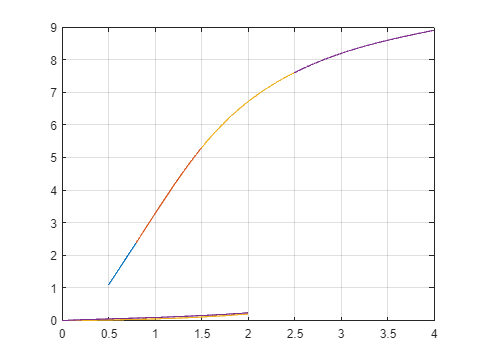

plot(x,y)

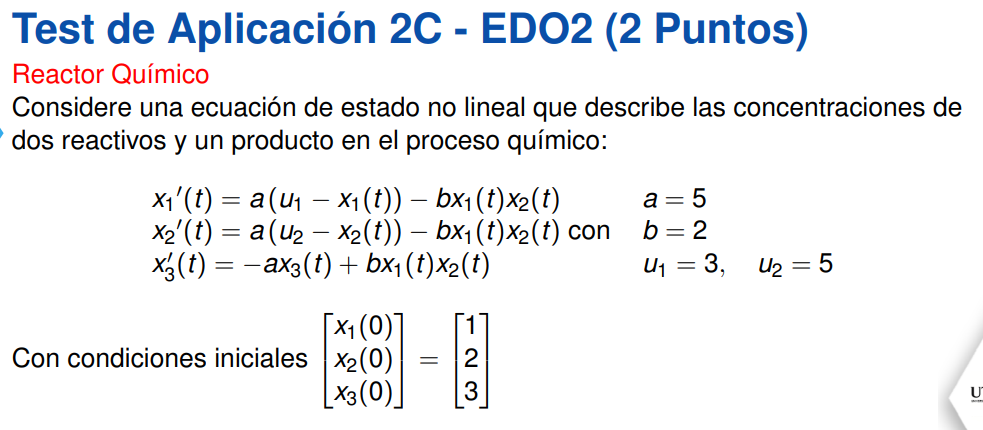

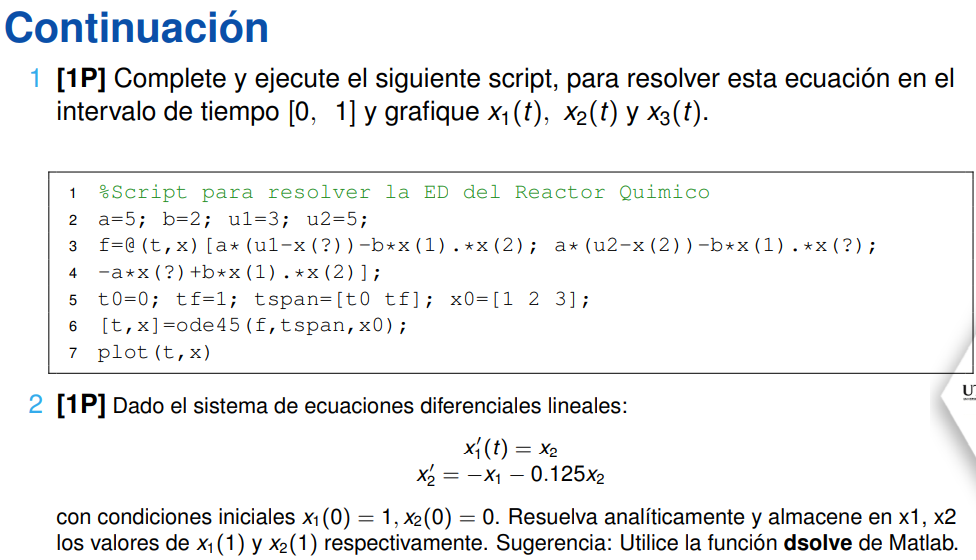

% item 1)
a = 5; b = 2; u1 = 3; u2 = 5;

f = @(t,x) [ a*(u1-x(1))-b*x(1).*x(2); a*(u2-x(2))-b*x(1).*x(2); -a*x(3)+b*x(1).*x(2)];

t0 = 0; tf = 1; 
tspan = [t0 tf]; 
x0 = [ 1 2 3];

[t,x] = ode45(f,tspan,x0)

t =                    0
   0.008372954771699
   0.016745909543397
   0.025118864315096
   0.033491819086794
   0.052935168636234
   0.072378518185675
   0.091821867735115
   0.111265217284555
   0.130479658678187


x =    1.000000000000000   2.000000000000000   3.000000000000000
   1.047636673619555   2.088637274605914   2.911362725394086
   1.090313210798231   2.170633338381470   2.829366661618530
   1.128393160511338   2.246420621077446   2.753579378922554
   1.162240856540473   2.316429635575294   2.683570364424706
   1.226686173091466   2.459235123811645   2.540764876188355
   1.274212327789793   2.577860572404225   2.422139427595775
   1.308056772602032   2.676212601055920   2.323787398944080
   1.331520016269339   2.758207487774972   2.241792512225028
   1.347293985552453   2.826500109539382   2.173499890460618



plot(t,x)


% item 2)
syms x1(t) x2(t)


eqn = [diff(x1,t) == x2, diff(x2,t) == -x1 - 0.125*x2]

$$eqn(t) = \left(\begin{array}{cc} \frac{\partial }{\partial t}x_{1}\left(t\right)=x_{2}\left(t\right) & \frac{\partial }{\partial t}x_{2}\left(t\right)=-x_{1}\left(t\right)-\frac{x_{2}\left(t\right)}{8} \end{array}\right)$$

cond = [x1(0) == 1, x2(0) == 0]

$$cond = \left(\begin{array}{cc} x_{1}\left(0\right)=1 & x_{2}\left(0\right)=0 \end{array}\right)$$


S = dsolve(eqn, cond)

S = struct with fields:
    x2: -(16*255^(1/2)*exp(-t/16)*sin((255^(1/2)*t)/16))/255
    x1: (16*255^(1/2)*((exp(-t/16)*sin((255^(1/2)*t)/16))/16 + (255^(1/2)*exp(-t/16)*cos((255^(1/2)*t)/16))/16))/255


sol_x1=matlabFunction(S.x1)

sol_x1 = function_handle with value:
    @(t)sqrt(2.55e+2).*((exp(t.*(-1.0./1.6e+1)).*sin((sqrt(2.55e+2).*t)./1.6e+1))./1.6e+1+(sqrt(2.55e+2).*exp(t.*(-1.0./1.6e+1)).*cos((sqrt(2.55e+2).*t)./1.6e+1))./1.6e+1).*(1.6e+1./2.55e+2)



sol_x2= matlabFunction(S.x2)

sol_x2 = function_handle with value:
    @(t)sqrt(2.55e+2).*exp(t.*(-1.0./1.6e+1)).*sin((sqrt(2.55e+2).*t)./1.6e+1).*(-1.6e+1./2.55e+2)



x1 = sol_x1(1)

x1 =    0.558551602703109


x2 = sol_x2(1)

x2 =   -0.791041527894495


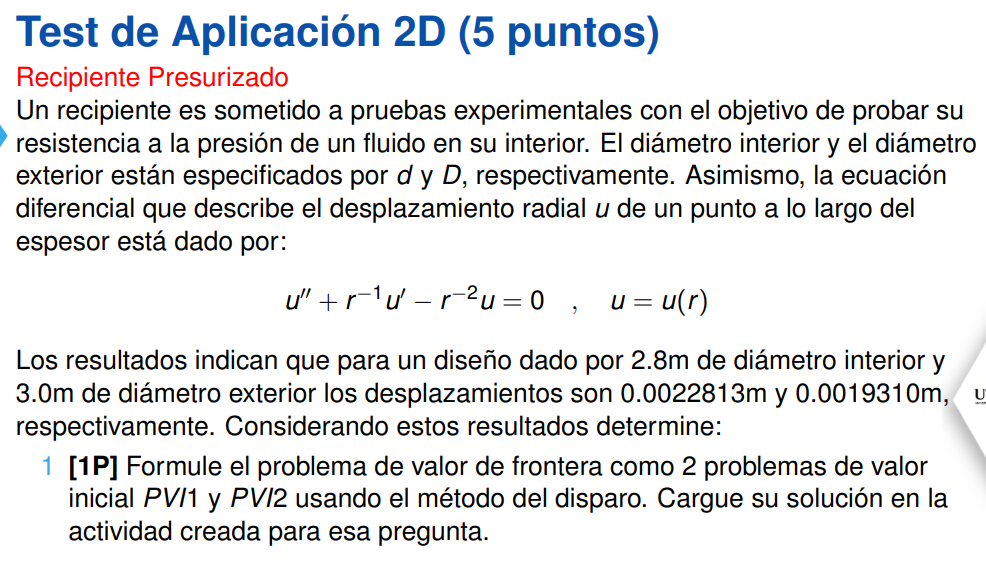

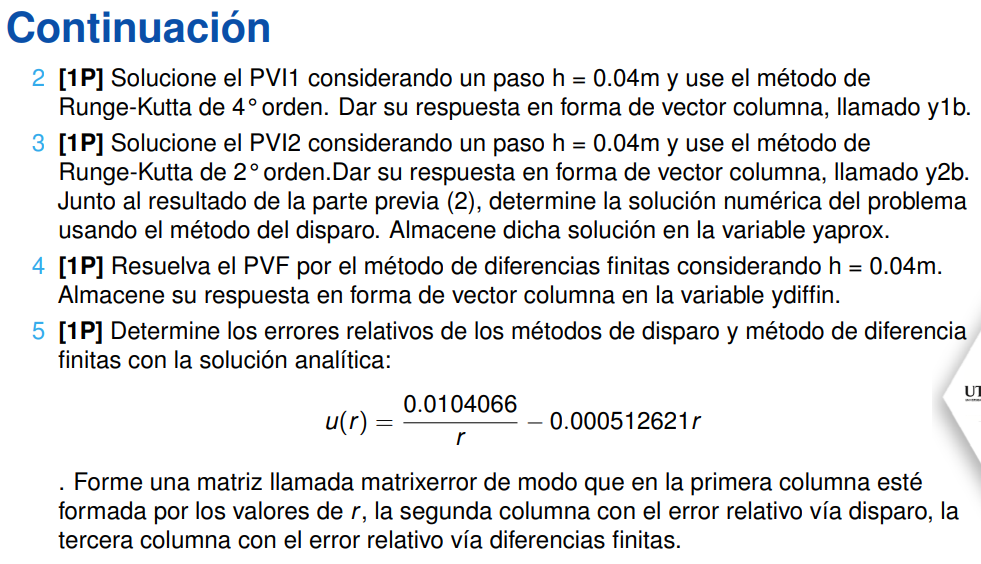

% item 2)
format long
h=0.04;
a=2.8;
b=3;
alfa = 0.0022813;
beta = 0.001931;

f = @(r,u) ( [ u(2); -u(2)/r+u(1)/(r^2) ]  );

y0 = [alfa;0];

sol1 = rk4(f,a,b,y0,h);
y1b = sol1(:,2)

y1b =    0.002281300000000
   0.002281529507179
   0.002282205278042
   0.002283308972983
   0.002284823243732
   0.002286731667255



% item 3)
y0 = [0;1];

sol2 = rk2(f,a,b,y0,h);
y2b = sol2(:,2)

y2b =                    0
   0.039714285714286
   0.078881061413113
   0.117522820855784
   0.155660842365421
   0.193315269823151



yaprox = y1b + ((beta - y1b(end))/y2b(end))*y2b

yaprox =    0.002281300000000
   0.002208448735630
   0.002137051242786
   0.002067047789675
   0.001998381872434
   0.001931000000000



% item 4)
alpha = 0.0022813;
beta = 0.001931;

a=2.8;
b=3;

p= @(x) (-1./x);
q= @(x) (1/(x.^2));
r= @(x) (0*x);

h=0.04;

tmp = diferenciafinita(p,q,r,a,b,alpha,beta,h);

ydiffin = [alpha; tmp; beta]

ydiffin =    0.002281300000000
   0.002208953248190
   0.002137618339062
   0.002067481925354
   0.001998501715530
   0.001931000000000



% item 5)
u = @(r) (0.0104066./r-0.000512621.*r)

u = function_handle with value:
    @(r)(0.0104066./r-0.000512621.*r)


a=2.8;
b=3;
h=0.04;

R = [a:h:b]';
U = u(R);

matrixerror = zeros(length(R),3);
matrixerror(:,1) = R;
matrixerror(:,2) = abs(yaprox-U)./abs(U);
matrixerror(:,3) = abs(ydiffin-U)./abs(U);
matrixerror

matrixerror =    2.800000000000000   0.000001778431439   0.000001778431439
   2.840000000000000   0.000001539095148   0.000226907132783
   2.880000000000000   0.000001429534004   0.000263933997732
   2.920000000000000   0.000001451301677   0.000208575312691
   2.960000000000000   0.000001606702113   0.000058363269362
   3.000000000000000   0.000001898839826   0.000001898839826


# Funciones

2A.1. Spline Cúbico Natural

function S = splinenatural(X,Y)
    N = length(X)-1;
    H = diff(X);
    E = diff(Y)./H;
    diagprinc = 2*(H(1:N-1)+H(2:N));
    diagsupinf = H(2:N-1);
    g0 = 0; 
    gn = 0;
    A = diag(diagprinc)+diag(diagsupinf,1)+diag(diagsupinf,-1);
    b = 6*diff(E');
    g = A\b;
    g = [g0 g' gn];

    for i = 1:N
        S(i,1) = (g(i+1)-g(i))/(6*H(i));
        S(i,2) = g(i)/2;
        S(i,3) = E(i)-H(i)*(g(i+1)+2*g(i))/6;
        S(i,4) = Y(i);
        xx = linspace(X(i),X(i+1),100);
        yy = S(i,1)*(xx-X(i)).^3+S(i,2)*(xx-X(i)).^2+S(i,3)*(xx-X(i))+S(i,4);
        plot(xx,yy)
        hold on
    end
    grid on
    %hold off
end

2A.1. Método de Newton con tolerancia

function z = newton(f,x0,Tol)
    syms x
    df = diff(f(x));
    dfu = matlabFunction(df);
    z = x0;
    error = 1;

    while error > Tol
        x1 = x0 - f(x0)/dfu(x0);
        z = [z; x1];
        error = abs(x1-x0)/abs(x1);
        x0 = x1;
    end
end

2A.2. Factorización QR de Gram-Schmidt

function [Q, R] = gs_c(A)
    [m,n]=size(A);
    Q=zeros(m,n);
    R=zeros(n);
    for j=1:n
        R(1:j-1,j)=Q(:,1:j-1)'*A(:,j);
        temp=A(:,j)-Q(:,1:j-1)*R(1:j-1,j);
        R(j,j)=norm(temp);
        Q(:,j)=temp/R(j,j);
    end
end

2A.2. Sustitución Regresiva

function [x]=sustireg(Ea,b)
    U = triu(Ea);
    % U: Matriz triangular superior
    [~,n] = size(U);
    x = zeros(n,1);
    for k=n:-1:1
        x(k)=(b(k)- U(k,k+1:n)*x(k+1:n))/U(k,k);
    end
end

2B. Método de Simpson 

function I = simp(f, a, b, h)
    X = [a:h:b];
    n = length(X)-1;
    Y = f(X);
    
    i_impar = [1:2:n-1]+1;
    i_par = [2:2:n-2]+1;
    
    I = (h/3)*( Y(1) + 4*sum(Y(i_impar) ) + 2*sum(Y(i_par) ) + Y(end) );
end

function I = simp2(f, a, b, h)
    I = (3*h/8)*(  f(a)+ 3*f(a+h)+3*f(a+2*h) + f(b));
end


2B. Cuadraturas de Gauss

function If = gaussnp(f,a,b,c,d,n)
    syms x
    lg = legendreP(n,x);
    dlg = matlabFunction(diff(lg,x));
    roots = double(vpasolve(lg==0));
    pesos = (2./((1-roots.^2).*dlg(roots).^2));

    syms t y
    x = ((b-a)*t+(a+b))/2;
    F = matlabFunction(f(x,y));
    Ix = ((b-a)/2)*sum(pesos.*(F(roots,y)));
    fy = matlabFunction(Ix);
    y = ((d-c)*t+(c+d))/2;
    g = matlabFunction(fy(y));
    If = ((d-c)/2)*sum(pesos.*(g(roots)));
end


2C.1. Aproximación de Euler para sistema de EDOs

function z = euler_sistema(f, a, b, y0, h)
    t = [a:h:b];
    z = [t(1) y0'];
    for k = 1:length(t)-1
        k1 = h*f(t(k), y0);
        y1 = y0+k1;
        z = [z; t(k+1) y1'];
        y0 = y1;
    end
end

2C.1. Aproximación de Runge-Kutta 2 para sistema de EDOs

function z = rk2_sistema(f, a, b, y0, h)
    t = [a:h:b];
    z = [t(1) y0'];
    for k = 1:length(t)-1
        k1 = h*f(t(k), y0);
        k2 = h*f(t(k+1), y0+k1);
        y1 = y0+1/2*(k1+k2);
        z = [z; t(k+1) y1'];
        y0 = y1;
    end
end

2D. Runge-Kutta de orden 4

function z=rk4(f,a,b,y0,h)
    t=[a:h:b];
    n=length(t);
    z=[t(1) y0'];
    for k=1:n-1
        k1=f(t(k),y0);
        k2=f(t(k)+h/2, y0+(h/2)*k1);
        k3=f(t(k)+h/2, y0+(h/2)*k2);
        k4=f(t(k)+h, y0+(h)*k3);
        y1=y0+(h/6)*(k1+2*k2+2*k3+k4);
        z=[z;t(k+1) y1'];
        y0=y1;
    end
end

2D. Runge-Kutta de orden 2

function z=rk2(f,a,b,y0,h)
    t=[a:h:b];
    n=length(t);
    z=[t(1) y0'];
    for k=1:n-1
        k1=f(t(k),y0);
        k2=f(t(k)+h, y0+h*k1);
        y1=y0+(h/2)*(k1+k2);
        z=[z;t(k+1) y1'];
        y0=y1;
    end
end

2D. Diferencias Finitas

function [ysol]=diferenciafinita(p,q,r,a,b,alpha,beta,h)
    xi=(a+h:h:b-h)';
    n=length(xi); % n+1: Numero de subintervalos
    D=eye(n).*(2+h^2*q(xi));
    B=diag((-1+(h/2)*p(xi)),1); B = B(1:end-1,1:end-1);
    A=diag((-1-(h/2)*p(xi)),-1); A = A(1:end-1,1:end-1);
    b=-h^2*r(xi);
    b(1)=b(1)+(1+(h/2)*p(xi(1)))*alpha;
    b(n)=b(n)+(1-(h/2)*p(xi(n)))*beta;
    M=A+D+B;
    ysol=linsolve(M,b);
end
